# Exercise Wheel LED Tracking

Code for tracking a red LED 'throwie' via camera recording. Initial videos were recorded on an iPhone SE with no stabilization or camera mounting. The goal of tracking being the total activity of the wheel, and not necessarily the directionally specific rotational information. 

frameNum=0;
comp=readvid('redWheelRedLED.MOV',frameNum);

A single frame can be seen here.

imagesc(squeeze(comp(1,20:510,60:580,:)));

Undefined function or variable 'comp'.

Focus the spectrum on mostly red pixels (the LED).

Error using axis (line 223)
Unknown command option yx.

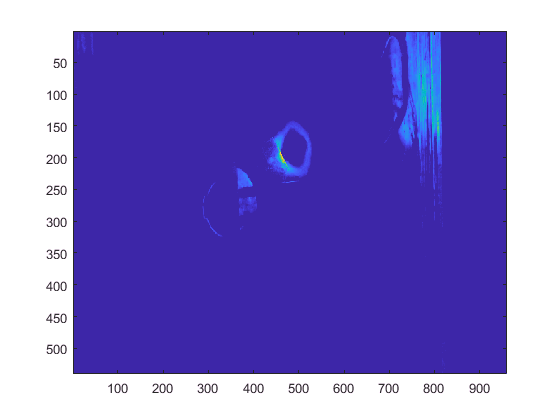

imagesc(transpose(squeeze(comp(1,:,:,1)-(comp(1,:,:,2)+comp(1,:,:,3)))))

A more detailed appraoch to a red filter shows less detail but gives more consistent results.

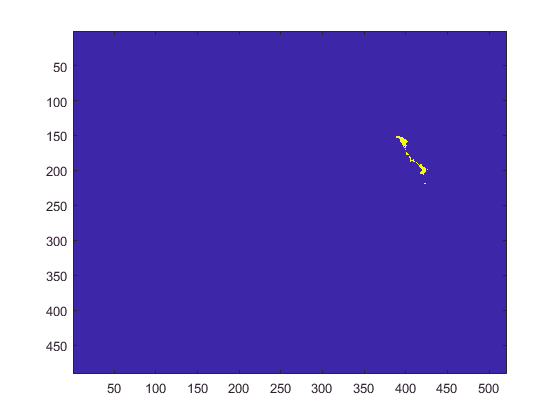

imagesc(squeeze(comp(1,20:510,60:580,1)>=240 & (comp(1,20:510,60:580,2)<=100 & comp(1,20:510,60:580,3)<=100)))

## Distance Approach

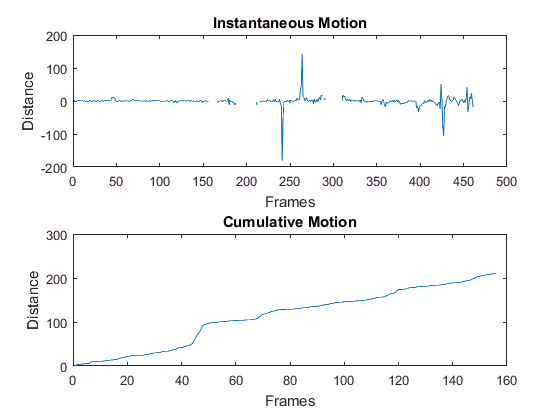

%comp=comp(:,1,:,:); % red channel
yrange=20:510;
xrange=60:580;
for i=1:size(comp,1)
    
    fr=squeeze(comp(i,yrange,xrange,1)>=240 & (comp(i,yrange,xrange,2)<=100 & comp(i,yrange,xrange,3)<=100));
    %fr=squeeze(comp(i,20:510,60:580,1)-(comp(i,20:510,60:580,2)+comp(i,20:510,60:580,3)));
    % pixels greather than 99% of the max intensity in the frame
    [indxR,indxC]=find(fr>max(fr)*.95); 
    % average position per frame
    posR(i)=smooth(mean(indxR),20); 
    posC(i)=smooth(mean(indxC),20);
    
end

figure;
subplot(2,1,1)
plot((diff(sqrt(posR.^2+posC.^2))))
title('Instantaneous Motion')
xlabel('Frames')
ylabel('Distance')
subplot(2,1,2)
plot(cumsum(abs(diff(sqrt(posR.^2+posC.^2)))))
xlabel('Frames')
ylabel('Distance')
title('Cumulative Motion')

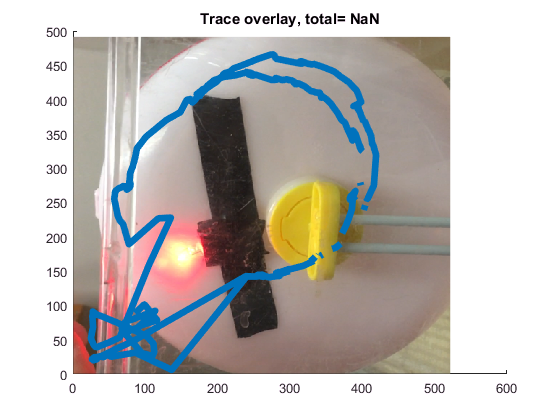



figure
motion=sum(abs(diff(sqrt(posR.^2+posC.^2))));
title(['Trace overlay, total= ' num2str(motion)])
hold on
imagesc(squeeze(comp(end,yrange,xrange,:)))
axis xy
plot(posR,posC,'LineWidth',5)

hold off

## Binary Masked Video

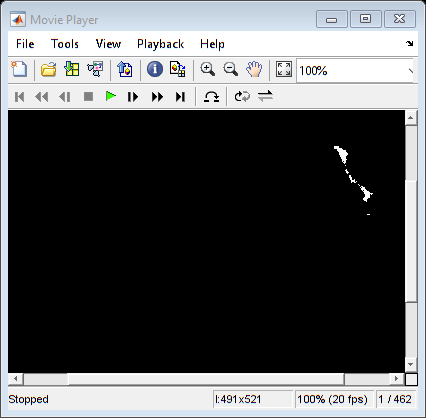

for i=1:size(comp,1)
    frm=uint8(squeeze(comp(i,yrange,xrange,1)>=240 & (comp(i,yrange,xrange,2)<=100 & comp(i,yrange,xrange,3)<=100)));
    scale=250;
    mov(i)=im2frame(frm.*scale,gray(255));
    
end

implay(mov)